# Real Dataset - depth study and DVG quantification - P0 example

Codigo necesario para obtener una estimación del numero de genomas defectivos por muestra

clearvars; format long; addpath('functions/'); %#ok<*AGROW>
load("ColorsAndOptions.mat","black","blue","blue_wa","lime","green","red","yellow_wa","mint","wesAnderson",'purple'); 
fontSize = 10; wideSize = [0 0 15.5 5]; whole_wideSize = [0 0 17 5]; noiseRed_size = [0 0 15.5 2.2];
sg_widthLine = 0.6; result_lineWidth = 1.2; lineWidth_X = 0.5; noise_lineWidth = 0.65; alphaNoiseLines = 0.925;
depthDot_size = 0.5;colLine_DVGs = wesAnderson(4,:); colLine_sg = purple;
colLine_noise = red; colLine_result = mint; colorDepth = black;alpha_outNoise = 0.5; alphaResult = 0.95;

## User: Input parameters

sample = "P1"; 
numReads_threshold_rel = 5*10^(-3); % Mayor es la tabla que mantenemos de DVGfinder
BPRI_th = 10; 
interval = 0.8;
joinLines_th = 5;
quantileNoise = 5;
min_deltaM2noise = 0.5; % Cuanto más pequeño más resolución se ve pero a costa del wt virus
deltaBases_X = 10;
minBPRI = 3;
firstBase = 10;
lastBase = 10;

## 1. Dataset pre-processing

### A. Load and merge data

sFL = string(char(sample)'); 
nameFile = "HCoVOC43.depth.bt.mapped/"+sample+"_nonhost_numbered_bt2_sorted_mapped_depth.txt";

#### Depth profile

[base, depth] = depthFile_read(nameFile); 
sgPos = load_sgPositions(nameFile);

#### DVGfinder output and minor merging 

numReads_threshold = numReads_threshold_rel*max(depth);
sampleDataset = datasetReading(sample,numReads_threshold,"Metasearch");
sampleDataset = mergeDataset(sampleDataset,BPRI_th);
BPRI = sort([sampleDataset.start' sampleDataset.ending']);
X_BPRI = unique([1 BPRI max(base)]); 
X = joinLines(X_BPRI,joinLines_th); clear BPRI X_BPRI
X(X<firstBase) = []; X(X>(max(base)-lastBase)) = [];
X = unique([1 X max(base)]);

Plot initial dataset after minor mergings (no lines at the moment)

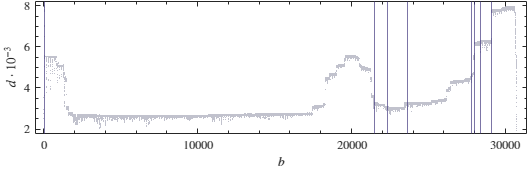

figure; tiledlayout(1,1,"TileSpacing","tight","Padding","tight"); 
nexttile; hold on; 
for i = 1:length(sgPos(:,1)); xline(mean(sgPos(i,:)),'Color',colLine_sg,'LineWidth',sg_widthLine); end 
scatter(base,depth,depthDot_size,'o','filled','CData',colorDepth)
xlim([-500 31400]); xticks([0 10000 20000 30000]); xticklabels({'0','10000','20000','30000'})
xlabel('$b$','Interpreter','latex'); 
ylim([1800 8200]); yticks([2000 4000 6000 8000]); yticks([2 4 6 8].*10^3); yticklabels({'2','4','6','8'})
ylabel('$d \cdot 10^{-3}$','Interpreter','latex'); 
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize); 
exportgraphics(gcf,'Figures/realDataDepthProfile_wsg.pdf','ContentType','vector')

### B. Noise level computation

#### (i) Obtain the median$\left(\bar{d_i } \right)$ of the interval and the relative distance$\left(\tilde{d_i } \right)$

medianDepth = zeros(1,length(X)-1); delta_medianDepth = deal([]);
for i = 1:length(X)-1
    Centroid = round(X(i)+1/2*(X(i+1)-X(i)));
    NData = round((X(i+1)-X(i))*interval/2);
    selectedBases = (Centroid-NData):1:(Centroid+NData);   
    medianDepth(i) = median(depth(ismember(base,selectedBases)));
    delta_medianDepth = [delta_medianDepth ...
        ((depth(ismember(base,selectedBases))-medianDepth(i))./medianDepth(i))'];
    clear Centroid NData selectedBases
end
clear i Centroid

#### (ii) Compute noise level

Deltas = sort(delta_medianDepth);
Qnoise = quantile(Deltas,1-quantileNoise/100); Q50 = quantile(Deltas,0.50);
upLim = Qnoise; lowLim = 2*Q50-Qnoise;
noiseLimit = (abs(upLim)+abs(lowLim))./2

noiseLimit =    0.009066868152626


lowerLim = medianDepth.*(1+lowLim);
upperLim = medianDepth.*(1+upLim);

### C. Removing non-informative separations.$\Delta m$ criterion

#### (i) Re-compute the interval median value removing outlyers

medianDepth = zeros(1,length(X)-1); 
for i = 1:length(X)-1    
    Centroid = round(X(i)+1/2*(X(i+1)-X(i)));
    NData = round((X(i+1)-X(i))*interval/2);
    selectedBases = (Centroid-NData):1:(Centroid+NData);  
    depth_selected = depth(ismember(base,selectedBases));
    depth_corrected = depth_selected(logical((depth_selected>lowerLim(i)).*(depth_selected<upperLim(i))));       
    medianDepth(i) = median(depth_corrected);
    clear selectedBases Centroid NData depth_corrected depth_selected
end

#### (ii) Separation selector

yhLine_th = noiseLimit*min_deltaM2noise;
[deltaMedians_forward, deltaMedians_backward] = deal(zeros(1,length(medianDepth)-1));
for i = 1:length(deltaMedians_forward)
    deltaMedians_forward(i) = abs(medianDepth(i)-medianDepth(i+1))./medianDepth(i); 
    deltaMedians_backward(i) = abs(medianDepth(i+1)-medianDepth(i))./medianDepth(i+1); 
end
thLineChange = logical((deltaMedians_backward >= yhLine_th)+(deltaMedians_forward >= yhLine_th));
X_deltaMedian = X([true thLineChange true]);
clear deltaMedians_forward deltaMedians_backward yhLine_th

### D. Select DVGs with BP and RI in X

sampleDataset_Xmedian = BPRI2consensus(sampleDataset,X_deltaMedian,deltaBases_X,minBPRI);
remove = logical(isnan(sampleDataset_Xmedian.start)+isnan(sampleDataset_Xmedian.ending));
sampleDataset_Xmedian_in = sampleDataset_Xmedian(~remove,:)

sampleDataset_Xmedian_in = 34×5 table
    sample     DVG_type     start    ending    read_counts_virema
    ______    __________    _____    ______    __________________

     "P1"     "deletion"     1312    19007            2916       
     "P1"     "deletion"     1353    18575            1071       
     "P1"     "deletion"     1438    18182             220       
     "P1"     "deletion"     1484    18283            3066       
     "P1"     "deletion"     1612    17439             582       
     "P1"     "deletion"    20368    26159             140       
     "P1"     "deletion"    20474    27740             139       
     "P1"     "deletion"    20486    23419             920       
     "P1"     "deletion"    20493    27296              52       
     "P1"     "deletion"    20524    25661             100       

X_deltaMedian_in = unique([1 sampleDataset_Xmedian_in.start' sampleDataset_Xmedian_in.ending' max(base)]);

### E. Plot pre-processing results

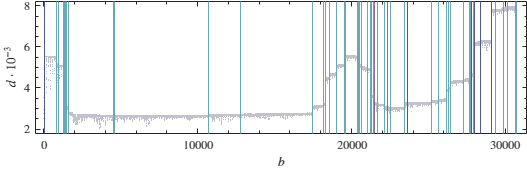

figure; tiledlayout(1,1,"TileSpacing","tight","Padding","tight")
nexttile; hold on; 
for i = 2:(length(X_deltaMedian_in)-1) 
    xline(X_deltaMedian_in(i),'-','Color',colLine_DVGs,'LineWidth',lineWidth_X,'Alpha',1);
end
for i = 1:length(sgPos(:,1)); xline(mean(sgPos(i,:)),'Color',colLine_sg,'LineWidth',sg_widthLine); end 
scatter(base,depth,depthDot_size,'o','filled','CData',colorDepth)
xlim([-500 31400]); xticks([0 10000 20000 30000]); xticklabels({'0','10000','20000','30000'})
xlabel('$b$','Interpreter','latex'); 
ylim([1800 8200]); yticks([2000 4000 6000 8000]); yticks([2 4 6 8].*10^3); yticklabels({'2','4','6','8'})
ylabel('$d \cdot 10^{-3}$','Interpreter','latex'); 
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize); 
exportgraphics(gcf,'Figures/realDataDepthProfile_preProcessed.pdf','ContentType','vector')

## 2. Noise reduction

DVGdataset = sampleDataset_Xmedian_in;
X = X_deltaMedian_in;

### (i) Obtain the median ($\bar{d_i }$) of the interval and $\tilde{d_i }$

medianDepth = zeros(1,length(X)-1); delta_medianDepth = [];
for i = 1:length(X)-1
    Centroid = round(X(i)+1/2*(X(i+1)-X(i)));
    NData = round((X(i+1)-X(i))*interval/2);
    selectedBases = (Centroid-NData):1:(Centroid+NData);   
    medianDepth(i) = median(depth(ismember(base,selectedBases)));
    delta_medianDepth = [delta_medianDepth ...
        ((depth(ismember(base,selectedBases))-medianDepth(i))./medianDepth(i))'];
    clear Centroid NData selectedBases
end; clear i

### (ii) Compute noise level

Deltas = sort(delta_medianDepth);
Qnoise = quantile(Deltas,1-quantileNoise/100); Q50 = quantile(Deltas,0.50);
upLim = Qnoise; lowLim = 2*Q50-Qnoise; clear Qnoise
noiseLimit = (abs(upLim)+abs(lowLim))./2; 
[upperLim,lowerLim,median_per_base] = deal([]);
for i = 1:length(medianDepth)  
    lowerLim = [lowerLim ones(1,X(i+1)-X(i)).*(medianDepth(i)*(1+lowLim))]; 
    upperLim = [upperLim ones(1,X(i+1)-X(i)).*(medianDepth(i)*(1+upLim))];  
    median_per_base = [median_per_base ones(1,X(i+1)-X(i)).*medianDepth(i)];
end
lowerLim(max(base)) = (medianDepth(i)*(1+upLim));
upperLim(max(base)) = (medianDepth(i)*(1+lowLim));
median_per_base(max(base)) = medianDepth(i);
d_ast = (depth-median_per_base')./median_per_base';

### (iii) Select bases inside noise limits

[bases_inNoise, bases_outNoise] = deal([]);
for i = 1:length(depth)
    if depth(i) > lowerLim(i) && depth(i) < upperLim(i)
        bases_inNoise= [bases_inNoise base(i)];
    else
        bases_outNoise= [bases_outNoise base(i)];
    end
end

### (iv) Plot the results of the noise study

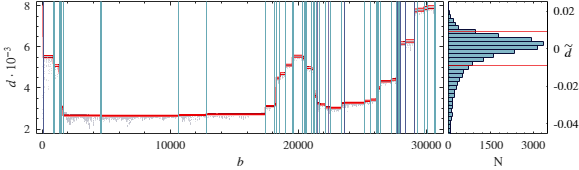

figure; tiledlayout(1,5,'TileSpacing','tight','Padding','tight')
nexttile([1 4]); hold on
for i = 2:(length(X)-1) 
    xline(X(i),'-','Color',colLine_DVGs,'LineWidth',lineWidth_X,'Alpha',1);
end
for i = 1:length(sgPos(:,1)); xline(mean(sgPos(i,:)),'Color',colLine_sg,'LineWidth',sg_widthLine); end 
scatter(base(bases_outNoise),depth(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
scatter(base(bases_inNoise),depth(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
plot(base,lowerLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth); 
plot(base,upperLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth);
xlim([-500 31400]); xticks([0 10000 20000 30000]); xticklabels({'0','10000','20000','30000'})
xlabel('$b$','Interpreter','latex'); 
ylim([1800 8200]); yticks([2000 4000 6000 8000]); yticks([2 4 6 8].*10^3); yticklabels({'2','4','6','8'})
ylabel('$d \cdot 10^{-3}$','Interpreter','latex'); 
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on

nexttile; hold on
histogram(delta_medianDepth,5000,"FaceColor",blue_wa,"EdgeColor",black,'Orientation','horizontal')
yline(lowLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth);
yline(upLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth); 
xlabel('N','Interpreter',"latex"); 
ylim([-0.045 0.025]); yticks([-0.04 -0.02 0 0.02]); yticklabels('')
xlim([0 3500]);xticks([0 1500 3000]);
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
yyaxis right; ylim([-0.045 0.025]); yticks([-0.04 -0.02 0 0.02]);
ylabel('$\tilde{d}$','Interpreter',"latex",'HorizontalAlignment','right','Rotation',0,'Position',[4450 0 -1],'VerticalAlignment','middle'); 
ax = gca; ax.YAxis(1).Color = 'k'; ax.YAxis(2).Color = 'k';
set(gcf,'renderer','Painters','Units','centimeters','Position',whole_wideSize); 
exportgraphics(gcf,'Figures/realData_NoiseReduction.pdf','ContentType','vector')

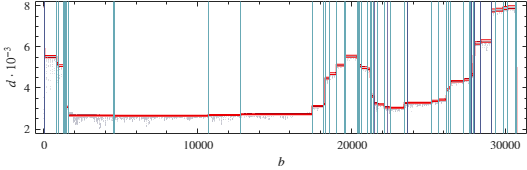

figure; tiledlayout(1,1,"TileSpacing","tight",'Padding','tight'); 
nexttile; hold on
for i = 2:(length(X)-1) 
    xline(X(i),'-','Color',colLine_DVGs,'LineWidth',lineWidth_X,'Alpha',1);
end
for i = 1:length(sgPos(:,1)); xline(mean(sgPos(i,:)),'Color',colLine_sg,'LineWidth',sg_widthLine); end 
scatter(base(bases_outNoise),depth(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
scatter(base(bases_inNoise),depth(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
plot(base,lowerLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth); 
plot(base,upperLim,'Color',[colLine_noise alphaNoiseLines],'LineWidth',noise_lineWidth);
xlim([-500 31400]); xticks([0 10000 20000 30000]); xticklabels({'0','10000','20000','30000'})
xlabel('$b$','Interpreter','latex'); 
ylim([1800 8200]); yticks([2000 4000 6000 8000]); yticks([2 4 6 8].*10^3); yticklabels({'2','4','6','8'})
ylabel('$d \cdot 10^{-3}$','Interpreter','latex');
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize);
exportgraphics(gcf,'Figures/realData_NoiseReduction_top.pdf','ContentType','vector')

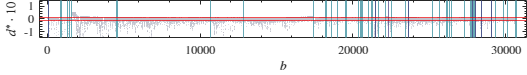

figure; tiledlayout(1,1,"TileSpacing","tight",'Padding','tight'); 
nexttile; hold on
for i = 2:(length(X)-1) 
    xline(X(i),'-','Color',colLine_DVGs,'LineWidth',lineWidth_X,'Alpha',1);
end
for i = 1:length(sgPos(:,1)); xline(mean(sgPos(i,:)),'Color',colLine_sg,'LineWidth',sg_widthLine); end 
scatter(base(bases_outNoise),d_ast(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
scatter(base(bases_inNoise),d_ast(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
yline(lowLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth);
yline(upLim,'-','Color',colLine_noise,'LineWidth',noise_lineWidth);
xlim([-500 31400]); xticks([0 10000 20000 30000]); xticklabels({'0','10000','20000','30000'})
xlabel('$b$','Interpreter','latex'); 
ylim([-0.15 0.15]); yticks([-0.1 0 0.1]); yticklabels({'-1','0','1'})
ylabel('$d^\ast \cdot 10$','Interpreter','latex'); 
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',noiseRed_size); 
exportgraphics(gcf,'Figures/realData_NoiseReduction_bottom.pdf','ContentType','vector')

## 3. DVGM computation

DVGM = DVG_Matrix_realData(DVGdataset,max(base)); 

## 4. DVG quantification

n = lsqlin(DVGM(:,bases_inNoise)',depth(bases_inNoise),[],[],[],[], ...
    zeros(length(DVGdataset.start)+1,1),[],[],optimset('Display','off'));
prop = n./sum(n);

### Identification of subgenomics

is_subgenomic = sg_identificator(sgPos,DVGdataset,BPRI_th); %save('realData_curated.mat',"DVGM","bases_inNoise","depth",'DVGdataset','is_subgenomic')

### Table of results

Results = DVGdataset;
Results.estim_prop = prop(2:end);
Results.is_subgenomic = is_subgenomic;
Results.nG = n(2:end);
Results = Results(:,[1 2 3 4 6 7 5 8]);
display(Results)

Results = 34×8 table
    sample     DVG_type     start    ending        estim_prop         is_subgenomic    read_counts_virema           nG       
    ______    __________    _____    ______    ___________________    _____________    __________________    ________________

     "P1"     "deletion"     1312    19007      0.0535962835804982          0                 2916           420.986447378843
     "P1"     "deletion"     1353    18575      0.0261460031631894          0                 1071           205.370825167292
     "P1"     "deletion"     1438    18182     0.00954489049498094          0                  220           74.9729136362026
     "P1"     "deletion"     1484    18283       0.165579235844073          

[Pearson_val, pval] = corr(Results.read_counts_virema,Results.nG)

Pearson_val =    0.900944202513796


pval =      3.854301951034773e-13


## 5. Results

V = 100*(prop(1)+sum(Results.estim_prop(Results.is_subgenomic == 1)));
D = 100*(sum(prop(2:end))-sum(Results.estim_prop(Results.is_subgenomic == 1)));
popProp = [n(1) + sum(Results.nG(Results.is_subgenomic == 1));
           sum(Results.nG(Results.DVG_type == "insertion"));
           sum(Results.nG(Results.DVG_type == "deletion"))-sum(Results.nG(Results.is_subgenomic == 1));
           sum(Results.nG(Results.DVG_type == "5cb/sb"))+sum(Results.nG(Results.DVG_type == "3cb/sb"))]./sum(n);
fprintf("Results: \n\t rho = " + num2str(D/V,3) + ". \n\t rho_Del = " + num2str(100*popProp(3)/V,3) + ".")

Results: 
	 rho = 2.47. 
	 rho_Del = 2.43.

### Final plots

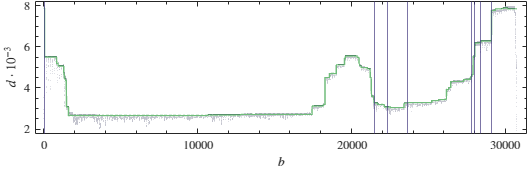

figure; tiledlayout(1,1,'TileSpacing','tight','Padding','tight')
nexttile; hold on; 
for i = 1:length(sgPos(:,1)); xline(mean(sgPos(i,:)),'Color',colLine_sg,'LineWidth',sg_widthLine); end 
scatter(base(bases_inNoise),depth(bases_inNoise),depthDot_size,'o','filled','CData',colorDepth)
scatter(base(bases_outNoise),depth(bases_outNoise),depthDot_size,'o','filled','CData',colorDepth,'MarkerFaceAlpha',alpha_outNoise,'MarkerEdgeAlpha',alpha_outNoise)
plot(base,DVGM'*n,'Color',[colLine_result alphaResult],'LineWidth',result_lineWidth)
xlim([-500 31400]); xticks([0 10000 20000 30000]); xticklabels({'0','10000','20000','30000'})
xlabel('$b$','Interpreter','latex'); 
ylim([1800 8200]); yticks([2000 4000 6000 8000]); yticks([2 4 6 8].*10^3); yticklabels({'2','4','6','8'})
ylabel('$d \cdot 10^{-3}$','Interpreter','latex'); 
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize); 
exportgraphics(gcf,'Figures/realData_result.pdf','ContentType','vector')

### Agreement with the local estimates

xModel = Results.nG./sum(Results.nG); yModel = Results.read_counts_virema./sum(Results.read_counts_virema);
mdl = fitlm(xModel,yModel)

mdl = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                        Estimate                  SE                 tStat                 pValue       
                   ___________________    __________________    ________________    ____________________

    (Intercept)    0.00398654288038845    0.0039122098171954     1.0190002752067        0.31584548012033
    x1               0.864457542066792    0.0736029833008435    11.7448709725994    3.85430195103472e-13


Number of observations: 34, Error degrees of freedom: 32
Root Mean Squared Error: 0.019
R-squared: 0.812,  Adjusted R-Squared: 0.806
F-statistic vs. constant model: 138, p-value = 3.85e-13

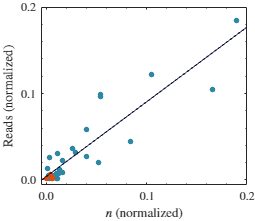

colorsDVGtype = wesAnderson([2 10 1],:); dotSize = 20;
figure; tiledlayout(1,1,'Padding','tight','TileSpacing','tight');
nexttile; hold on
scatter(xModel(Results.DVG_type == "deletion"),yModel(Results.DVG_type == "deletion"),dotSize,'o','filled','CData',colorsDVGtype(1,:))
scatter(xModel(Results.DVG_type == "insertion"),yModel(Results.DVG_type == "insertion"),dotSize,'o','filled','CData',colorsDVGtype(2,:))
scatter(xModel(Results.DVG_type == "cb/sb"),yModel(Results.DVG_type == "sb/sb"),dotSize,'o','filled','CData',colorsDVGtype(3,:))
plot([-.1 0.2],mdl.Coefficients.Estimate(1)+[-.1 0.2].*mdl.Coefficients.Estimate(2),'Color',black)
xlabel('$n$ (normalized)','Interpreter','latex'); ylabel('Reads (normalized)','Interpreter','latex'); 
xticks([0 0.1 0.2]); xtickformat('%.1f'); yticks([0 0.1 0.2]); ytickformat('%.1f')
axis([-.005 .2 -.005 .2])
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',[0 0 7.5 6.5]); 
exportgraphics(gcf,'Figures/estimComparison.pdf','ContentType','vector')

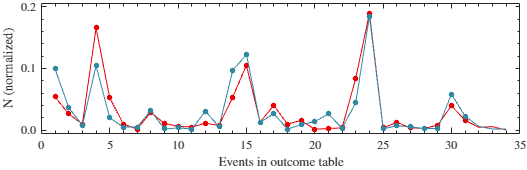

TabInp = 1:1:length(Results.DVG_type);
figure; tiledlayout(1,1,'Padding','tight','TileSpacing','tight');
nexttile; hold on
scatter(TabInp(Results.DVG_type == "deletion"),xModel(Results.DVG_type == "deletion"),dotSize,'o','filled','CData',red)
scatter(TabInp(Results.DVG_type == "insertion"),xModel(Results.DVG_type == "insertion"),dotSize,'s','filled','CData',red)
scatter(TabInp(Results.DVG_type == "cb/sb"),xModel(Results.DVG_type == "cb/sb"),dotSize,'d','filled','CData',red)
plot(TabInp,xModel,'LineWidth',lineWidth_X,'Color',red)
scatter(TabInp(Results.DVG_type == "deletion"),yModel(Results.DVG_type == "deletion"),dotSize,'o','filled','CData',blue_wa)
scatter(TabInp(Results.DVG_type == "insertion"),yModel(Results.DVG_type == "insertion"),dotSize,'s','filled','CData',blue_wa)
scatter(TabInp(Results.DVG_type == "cb/sb"),yModel(Results.DVG_type == "cb/sb"),dotSize,'d','filled','CData',blue_wa)
plot(TabInp,yModel,'LineWidth',lineWidth_X,'Color',blue_wa)
xlabel('Events in outcome table','Interpreter','latex'); ylabel('N (normalized)','Interpreter','latex'); 
yticks([0 0.1 0.2]); ytickformat('%.1f')
axis([0 35 -.005 .205])
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on'); box on
set(gcf,'renderer','Painters','Units','centimeters','Position',wideSize); 
exportgraphics(gcf,'Figures/estimComparison_table.pdf','ContentType','vector')

### Population distribution

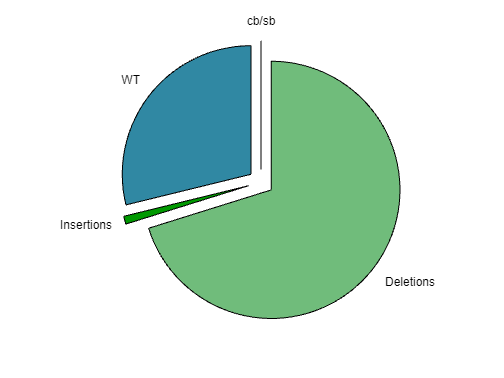

colorsPie = [blue_wa; green; mint; lime];
figure; ax = gca;
pie(ax,popProp,[1 1 1 1],["WT","Insertions","Deletions","cb/sb"]');
ax.Colormap = colorsPie;
ax.TickLabelInterpreter = "latex";
set(gca,'TickLabelInterpreter','latex','FontSize',fontSize,'XMinorTick','on','YMinorTick','on');

fprintf("Viral genomes proportion: "+num2str(V,3)+ "%%. \nDefective genomes proportion: "+ ...
    num2str(D,3)+"%%. \nProportion of deletions in the sample: "+num2str(100*popProp(3),3)+"%%. \n")

Viral genomes proportion: 28.8%. 
Defective genomes proportion: 71.2%. 
Proportion of deletions in the sample: 70.2%. 
